%informative likelihood 

mu = [1 0];
Sigma = [0.05 0; 0 .087];

x1 = 0:.05:2;
x2 = -1.5:.05:1.5;
[X1,X2] = meshgrid(x1,x2);
X = [X1(:) X2(:)];

P = mvnpdf(X,mu,Sigma);
P = reshape(P,length(x2),length(x1));

%prior probability 

mu = [1.08 0];
Sigma = [0.01 0; 0 .131];

x1 = 0:.05:2;
x2 = -1.5:.05:1.5;
[X1,X2] = meshgrid(x1,x2);
X = [X1(:) X2(:)];

Q = mvnpdf(X,mu,Sigma);
Q = reshape(Q,length(x2),length(x1));

%posterior 

Z= P.*Q

Z =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    

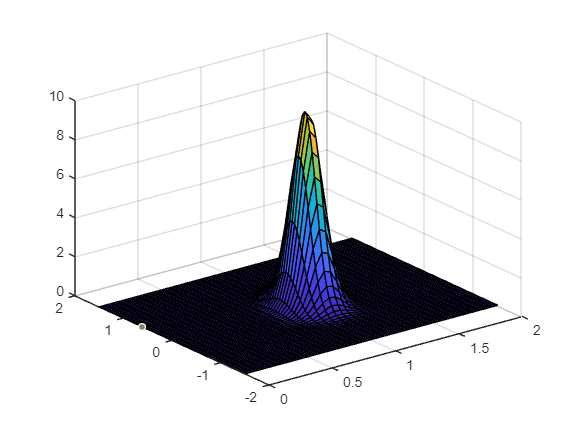


surf(X1,X2,Z)